# Lab 6 – Mini Project: Image Enhancement and Edge Detection

Course: Mathematical Algorithms (DSP)

**Lecture: 9 – Image Processing LabsProject Objective**

The objective of this mini-project is to combine several digital signal processing techniques into a single image-processing pipeline.

The selected image will be processed using median filtering, contrast enhancement, Canny edge detection, and frequency-domain low-pass filtering.

The main problem addressed is how to improve the visibility of object boundaries while reducing unwanted noise and image details.

The different processing stages will be compared visually to understand how spatial-domain and frequency-domain operations affect the image.

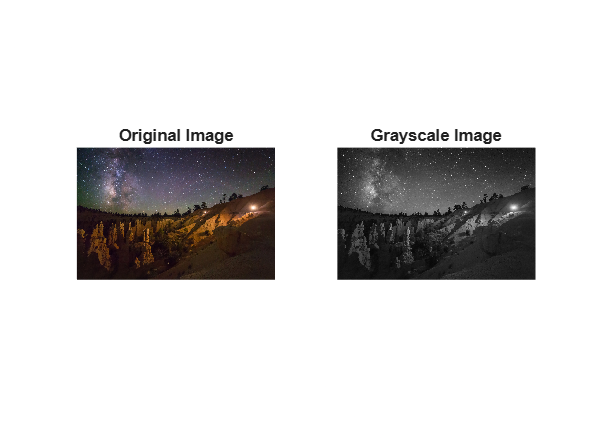


%% Lab 6: Mini Project - Your Image Pipeline
% Section 1: Load and Prepare the Image

close all;
clear;
clc;

% Load the selected image
I0 = imread('testimg.jpg');

% Convert to grayscale if the image is RGB
if size(I0, 3) == 3
    I = rgb2gray(I0);
else
    I = I0;
end

% Convert to double precision
I = im2double(I);

% Display original and grayscale images
figure;

subplot(1,2,1);
imshow(I0);
title('Original Image');

subplot(1,2,2);
imshow(I);
title('Grayscale Image');


% Display image information
[M, N] = size(I);

fprintf('Image size: %d x %d\n', M, N);

Image size: 1200 x 1800


fprintf('Data type: %s\n', class(I));

Data type: double


fprintf('Intensity range: %.3f to %.3f\n', ...
    min(I(:)), max(I(:)));

Intensity range: 0.000 to 1.000


**Section 1 – Image Selection and Preparation**

For this mini-project, I selected a photograph of an object to investigate how digital signal processing techniques can improve image quality and detect object boundaries.

The image was loaded into MATLAB using the `imread` function and converted to grayscale when necessary.

The grayscale image was then converted to double precision using `im2double`, representing pixel intensities between 0 and 1.

The image dimensions and intensity range were checked before processing.

This prepared image will be used as the input for noise reduction, contrast enhancement, edge detection, and frequency-domain filtering.

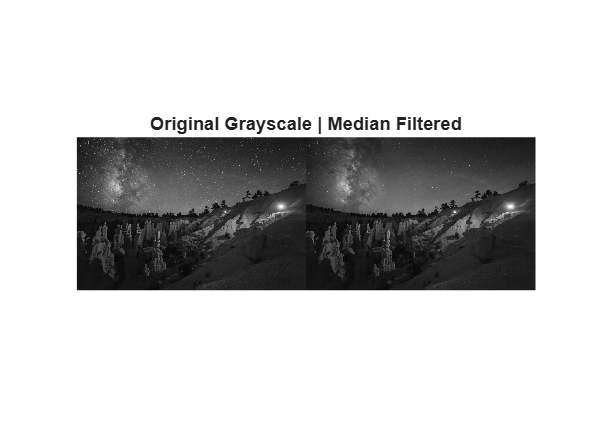


%% 2) Pre-processing: Noise Removal

% Apply a 3x3 median filter
I_filt = medfilt2(I, [3 3]);

% Compare the original and filtered images
figure;

montage({I, I_filt}, 'Size', [1 2]);

title('Original Grayscale | Median Filtered');


% Measure the difference between the two images
MSE_filter = immse(I_filt, I);

fprintf('MSE between original and filtered image: %.6f\n', ...
    MSE_filter);

MSE between original and filtered image: 0.000757


**Section 2 – Noise Removal Using Median Filtering**

A 3×3 median filter was applied to the grayscale image using MATLAB's `medfilt2` function.

Median filtering is a nonlinear spatial-domain operation that replaces each pixel with the median intensity value of its neighboring pixels.

This technique is particularly useful for removing isolated noise, such as salt-and-pepper noise, while preserving important image boundaries.

The original and filtered images were displayed side by side to compare their appearance.

I also calculated the Mean Square Error (MSE) between the original and filtered images to measure how much the pixel values changed during filtering.

This stage prepares the image for contrast enhancement and edge detection by reducing isolated intensity variations.

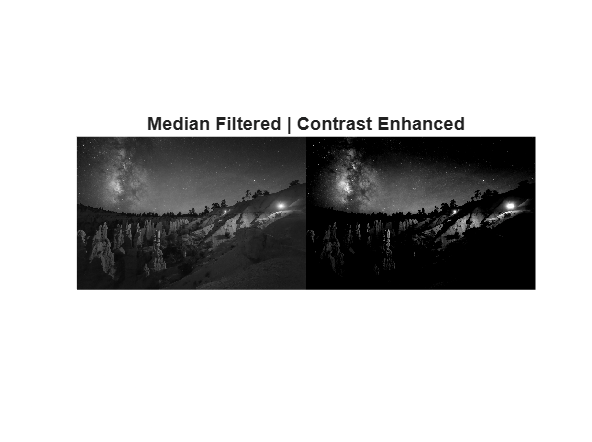


%% 3) Enhance Contrast

% Enhance contrast of the median-filtered image
I_enh = imadjust(I_filt, [0.2 0.8], [0 1]);

% Display filtered and enhanced images
figure;

montage({I_filt, I_enh}, 'Size', [1 2]);

title('Median Filtered | Contrast Enhanced');


% Display intensity ranges
fprintf('Filtered image range: %.3f to %.3f\n', ...
    min(I_filt(:)), max(I_filt(:)));

Filtered image range: 0.000 to 0.996



fprintf('Enhanced image range: %.3f to %.3f\n', ...
    min(I_enh(:)), max(I_enh(:)));

Enhanced image range: 0.000 to 1.000


**Section 3 – Contrast Enhancement**

Contrast enhancement was applied to the median-filtered image using MATLAB's `imadjust` function.

The input intensity range of 0.2 to 0.8 was mapped to the output range of 0 to 1. This increases the contrast between darker and brighter regions of the image.

Pixel intensities below 0.2 were mapped to black, while intensities above 0.8 were mapped to white.

The median-filtered and contrast-enhanced images were displayed side by side to compare their appearance.

This stage demonstrates how point-wise intensity transformations can improve contrast and potentially make object boundaries easier to detect.

However, contrast stretching may also remove some details in very dark or bright regions.

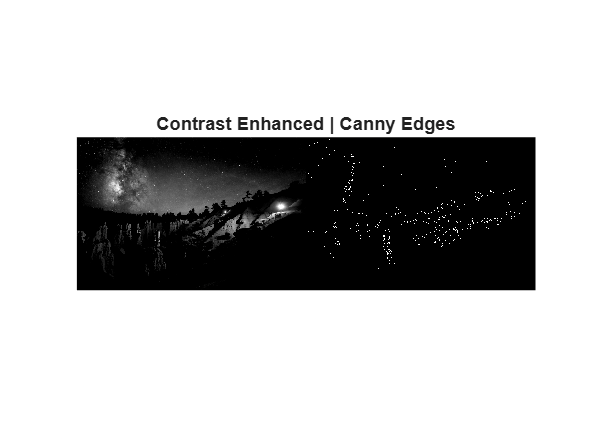


%% 4) Extract Features - Canny Edge Detection

% Apply Canny edge detection to the enhanced image
edges = edge(I_enh, 'Canny', [0.1 0.25]);

% Display the enhanced image and detected edges
figure;

montage({I_enh, edges}, 'Size', [1 2]);

title('Contrast Enhanced | Canny Edges');


% Count the detected edge pixels
num_edges = nnz(edges);

% Calculate percentage of edge pixels
edge_percentage = 100 * num_edges / numel(edges);

fprintf('Number of edge pixels: %d\n', num_edges);

Number of edge pixels: 24797


fprintf('Percentage of edge pixels: %.2f%%\n', ...
    edge_percentage);

Percentage of edge pixels: 1.15%


**Section 4 – Feature Extraction Using Canny Edge Detection**

Canny edge detection was applied to the contrast-enhanced image using MATLAB's `edge` function with threshold values of 0.10 and 0.25.

The purpose of this stage was to extract object boundaries and other important intensity transitions from the processed image.

Canny combines Gaussian smoothing, gradient calculation, non-maximum suppression, and double-threshold hysteresis to produce a binary edge map.

The enhanced image and detected edges were displayed side by side to compare the results.

I also calculated the number and percentage of detected edge pixels to measure how much of the image was classified as edges.

This stage demonstrates how spatial derivatives can be used for feature extraction and how edges relate to high-frequency components in digital images.

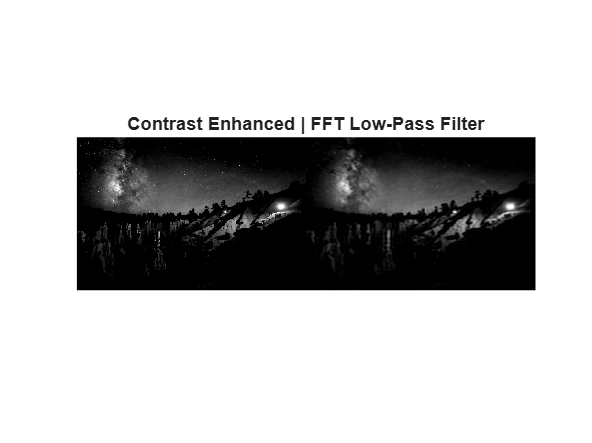


%% 5) Frequency-Domain Low-Pass Filtering

% Compute the 2D Fourier Transform
F = fftshift(fft2(I_enh));

% Get image dimensions
[M, N] = size(F);

% Create frequency coordinate grids
[u, v] = meshgrid( ...
    -floor(N/2):ceil(N/2)-1, ...
    -floor(M/2):ceil(M/2)-1);

% Create circular low-pass filter mask
H = double(sqrt(u.^2 + v.^2) < 60);

% Apply frequency-domain filtering
F_filtered = F .* H;

% Convert back to spatial domain
I_lp = real(ifft2(ifftshift(F_filtered)));

% Display enhanced and low-pass filtered images
figure;

montage({I_enh, I_lp}, 'Size', [1 2]);

title('Contrast Enhanced | FFT Low-Pass Filter');

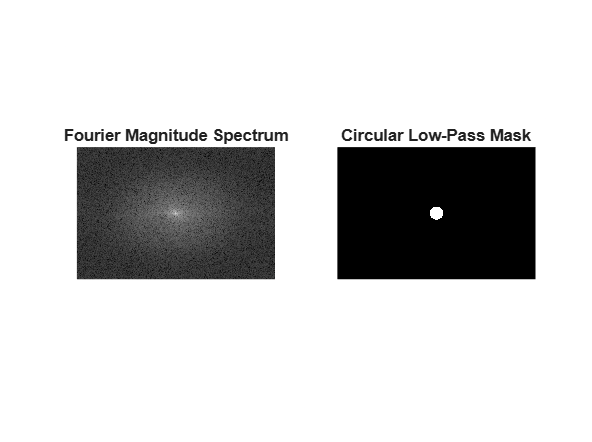


% Display Fourier magnitude spectrum and filter mask
figure;

subplot(1, 2, 1);
imshow(log(1 + abs(F)), []);
title('Fourier Magnitude Spectrum');

subplot(1, 2, 2);
imshow(H, []);
title('Circular Low-Pass Mask');


% Calculate difference between images
MSE_lp = mean((I_enh(:) - I_lp(:)).^2);

fprintf('MSE between enhanced and LP image: %.6f\n', ...
    MSE_lp);

MSE between enhanced and LP image: 0.001338


**Section 5 – Frequency-Domain Low-Pass Filtering**

Frequency-domain low-pass filtering was applied to the contrast-enhanced image using the two-dimensional Fast Fourier Transform (FFT).

The `fft2` function converted the image from the spatial domain into the frequency domain, while `fftshift` moved the zero-frequency component to the center of the spectrum.

A circular low-pass filter mask with a cutoff radius of 60 frequency bins was created. The mask retained lower spatial frequencies and removed higher-frequency components.

The filtered spectrum was converted back into an image using the inverse Fourier Transform (`ifft2`).

The enhanced and low-pass filtered images were displayed for comparison. The Fourier magnitude spectrum and filter mask were also visualized to show how the filtering operation works.

This stage demonstrates the relationship between image smoothing and frequency-domain filtering. Removing high-frequency components can reduce fine details and noise, but it may also blur important edges or introduce ringing artifacts.

The Mean Square Error (MSE) was calculated to measure the difference between the enhanced and low-pass filtered images.

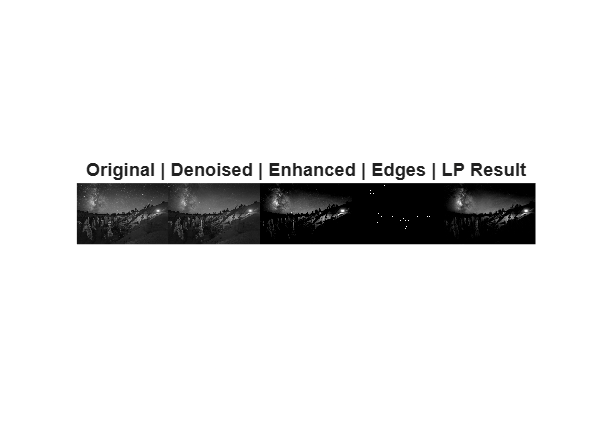


%% 6) Final Pipeline Visualization

% Display all five processing stages
figure('Name', 'Lab 6 - Complete Image Pipeline');

montage({I, I_filt, I_enh, edges, I_lp}, ...
    'Size', [1 5]);

title('Original | Denoised | Enhanced | Edges | LP Result');


% Print a summary of the processing pipeline
fprintf('\n=== Lab 6: Image Processing Pipeline ===\n');


=== Lab 6: Image Processing Pipeline ===


fprintf('1. Original grayscale image loaded\n');

1. Original grayscale image loaded


fprintf('2. Median filtering completed\n');

2. Median filtering completed


fprintf('3. Contrast enhancement completed\n');

3. Contrast enhancement completed


fprintf('4. Canny edge detection completed\n');

4. Canny edge detection completed


fprintf('5. FFT low-pass filtering completed\n');

5. FFT low-pass filtering completed


**Section 6 – Final Pipeline Visualization**

The results of the image-processing pipeline were combined into a single figure using MATLAB's `montage` function.

The figure displays five stages: the original grayscale image, the median-filtered image, the contrast-enhanced image, the Canny edge map, and the frequency-domain low-pass filtered image.

Each stage demonstrates a different digital signal processing technique.

Median filtering is used to reduce isolated noise, while contrast enhancement adjusts pixel intensity values to improve visibility. Canny edge detection identifies important intensity transitions, and FFT low-pass filtering removes higher-frequency components to produce a smoother image.

Displaying all five results together makes it easier to compare the effects of the different processing operations and evaluate their usefulness for the selected image.

## Section 7 – Final Report and Reflections

**7.1 Processing Pipeline**

In this mini-project, I developed an image-processing pipeline using MATLAB to apply several digital signal processing techniques to my selected photograph.

The main objective was to improve image quality and extract useful features by combining noise reduction, contrast enhancement, edge detection, and frequency-domain filtering.

First, the original image was converted to grayscale and double precision to prepare it for processing.

Next, a 3×3 median filter was applied to reduce isolated noise and small intensity variations. After filtering, contrast enhancement was performed using `imadjust` to increase the differences between darker and brighter image regions.

Canny edge detection was then applied to the enhanced image to identify object boundaries and significant intensity transitions.

Finally, a two-dimensional Fast Fourier Transform (FFT) was used to apply a circular low-pass filter in the frequency domain. The filtered spectrum was converted back to the spatial domain using the inverse FFT.

The results of all five stages were displayed together to compare the effects of the different processing techniques.

**7.2 Relationship to DSP Operations**

Each stage of the pipeline demonstrates an important digital signal processing concept.

**Median Filtering:** This is a nonlinear spatial-domain filtering technique. It replaces each pixel with the median value of its neighboring pixels and is useful for reducing isolated noise.

**Contrast Enhancement:** This is a point-wise intensity transformation. It changes pixel values to improve the contrast between different image regions.

**Canny Edge Detection:** This technique uses smoothing, spatial gradients, non-maximum suppression, and thresholding to identify image boundaries. Edges are associated with high spatial-frequency components because they represent rapid intensity changes.

**Frequency-Domain Filtering:** The FFT transforms the image into its spatial-frequency representation. A circular low-pass mask retains lower frequencies and removes higher frequencies, producing a smoother image after the inverse transform.

These operations demonstrate how images can be processed using both spatial-domain and frequency-domain techniques.

**7.3 Improvements and Limitations**

One advantage of the pipeline is that it combines several processing techniques in a logical sequence. Noise reduction is performed before contrast enhancement and edge detection, which can help reduce unwanted responses caused by isolated noise.

Contrast enhancement can make object details more visible, while Canny edge detection provides a binary representation of intensity boundaries.

However, the pipeline also has some limitations.

Median filtering may remove small image details, especially when the filter size is increased.

The fixed contrast adjustment range of 0.2 to 0.8 may not be suitable for every image and can cause information loss in very dark or bright regions.

Canny edge detection depends on the selected thresholds. Some important boundaries may be missed, while background textures may be detected as unwanted edges.

The frequency-domain low-pass filter can smooth the image, but it may also blur important details and introduce ringing artifacts because of its sharp cutoff.

Possible improvements include testing different median-filter sizes, using adaptive contrast enhancement, adjusting the Canny thresholds, and comparing different low-pass filter designs.

**7.4 Conclusion**

This mini-project combined several DSP image-processing techniques into one MATLAB pipeline.

The project demonstrated how median filtering, contrast enhancement, Canny edge detection, and FFT-based low-pass filtering can be used to process a digital image.

It also showed that different techniques have different purposes: filtering reduces unwanted variations, contrast enhancement changes intensity differences, edge detection extracts boundaries, and frequency-domain filtering controls spatial-frequency components.

The pipeline provides a practical example of how digital signal processing concepts can be applied to image enhancement and feature extraction.